# SISO system

## Define plant

### Parameters (spring mass damper)

k = 1;
m = 1;
b = 0.2;

### State Space Model

A = [0,1;-k/m,-b/m];
B = [0;1/m];
C = [1,0];
D = [0];
Ca = [C;eye(2)];
Da = [D;0;0];
plant = ss(A,B,C,D);
plant.InputName = {'u force'};
plant.StateName={'x','xdot'};
plant.OutputName={'position'};

plant_aug = ss(A,B,Ca,Da);
plant_aug.InputName = {'u force'};
plant_aug.StateName={'x','xdot'};
plant_aug.OutputName={'position','x','xdot'};

### Responce

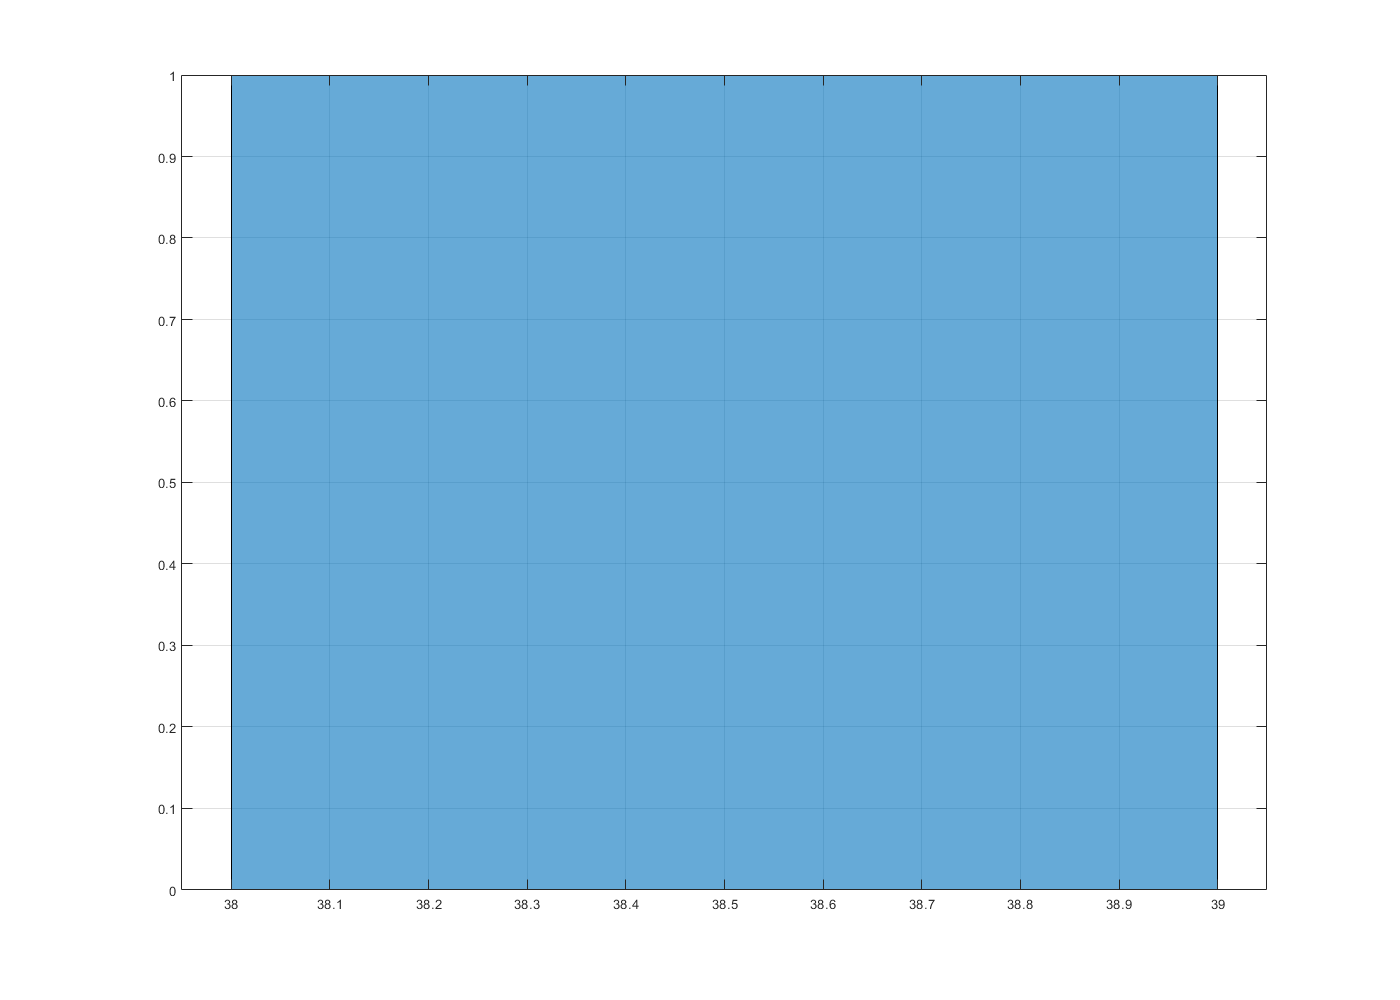

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
    cascade: [1×1 struct]
         h2: [1×1 struct]


report.base = test_plant(plant)

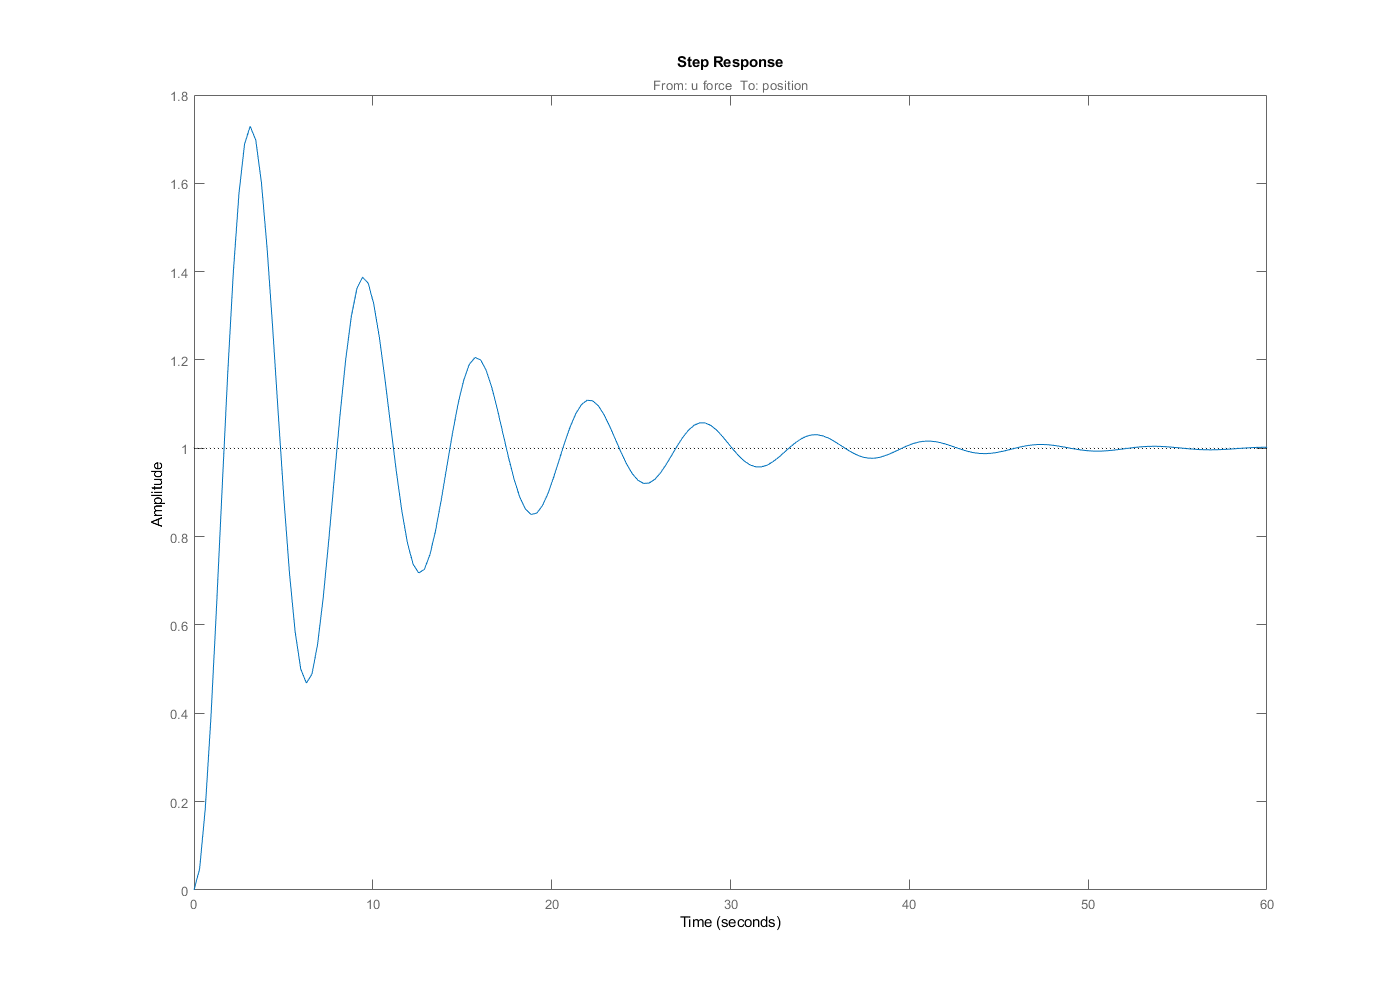


step(plant)

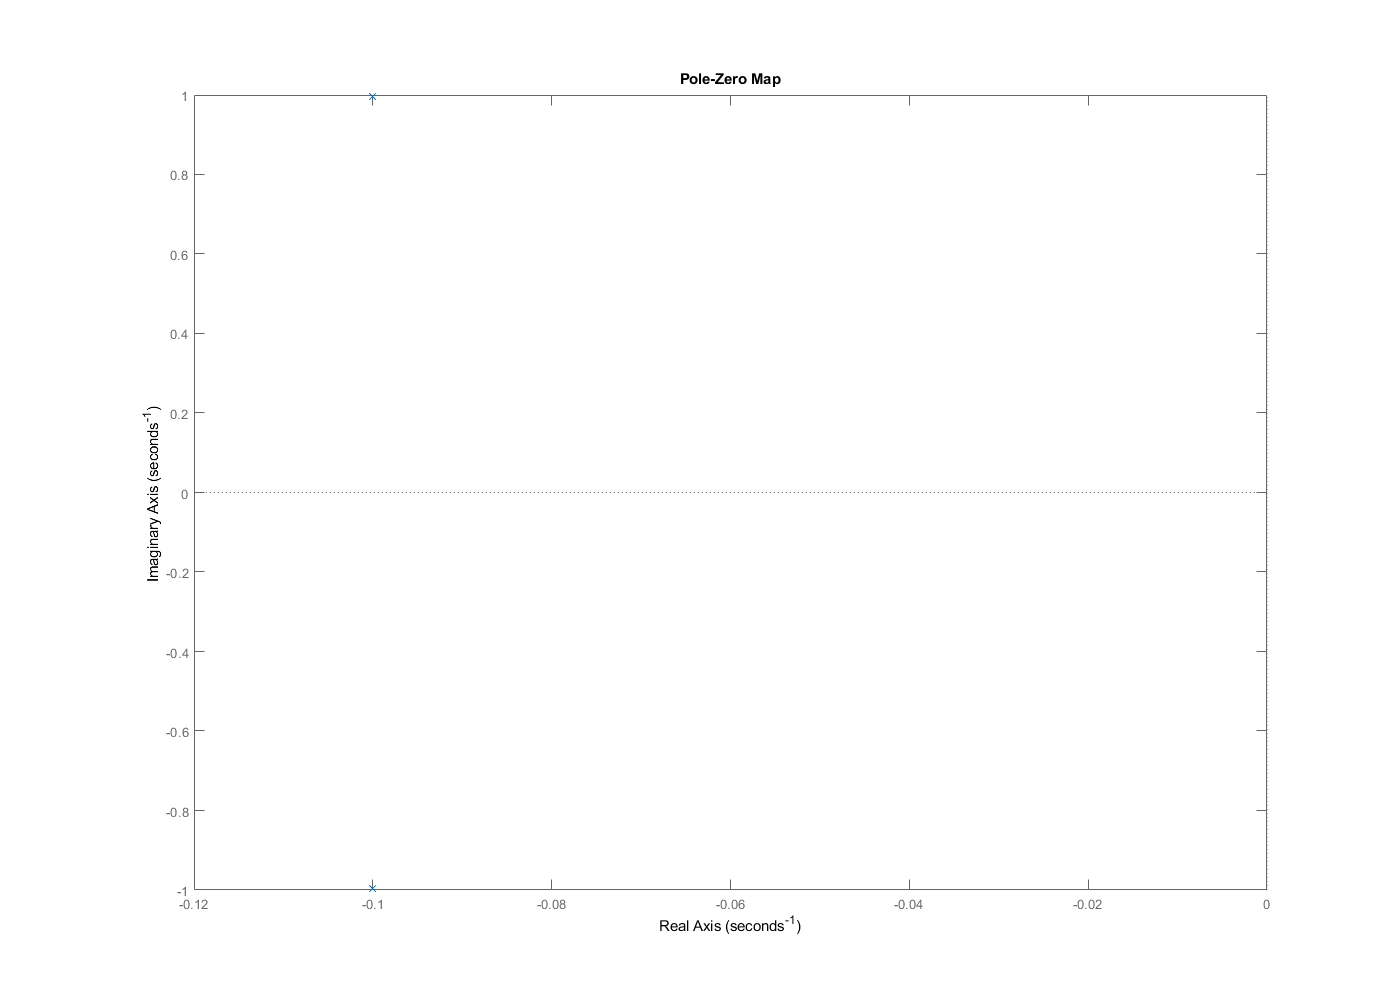

pzplot(plant)

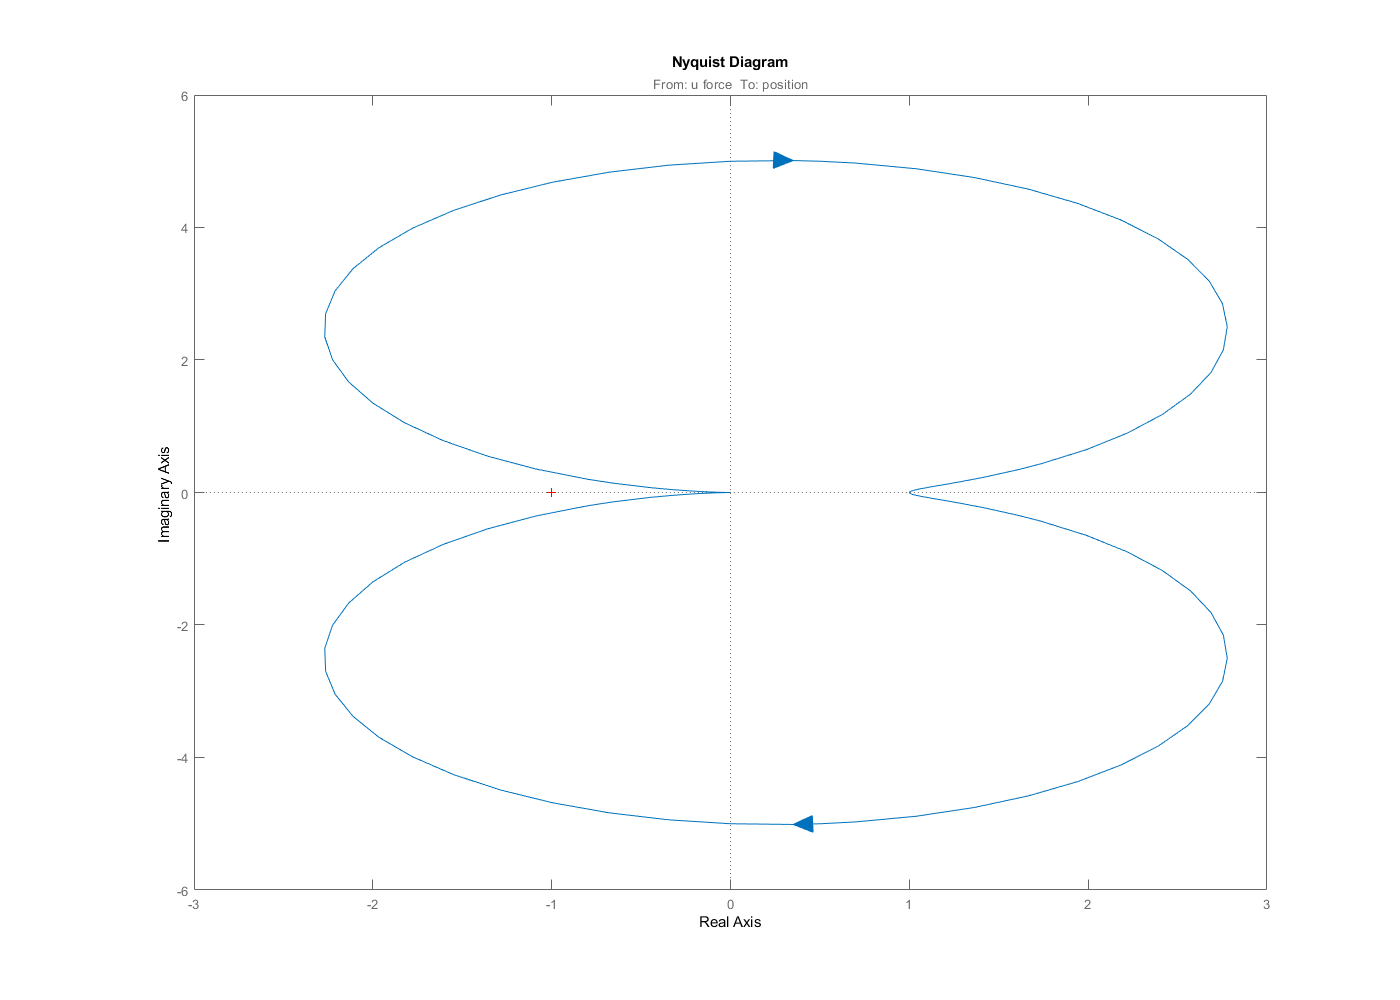

nyquist(plant)

## Controller

### LQR

#### Parameters (gains)

Q = diag([1,1]);
R = 1;

#### Controler

[K_LQR,S_LQR,e_LQR] = lqr(plant,Q,R,[0,0]');
controller = ss(K_LQR);
controller.InputName = {'x','xdot'};
controller.OutputName={'u force'};
LQR_plant = feedback(plant_aug,controller,'name',-1);

### Responce

report.lqr = test_plant(LQR_plant)

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
    cascade: [1×1 struct]
         h2: [1×1 struct]


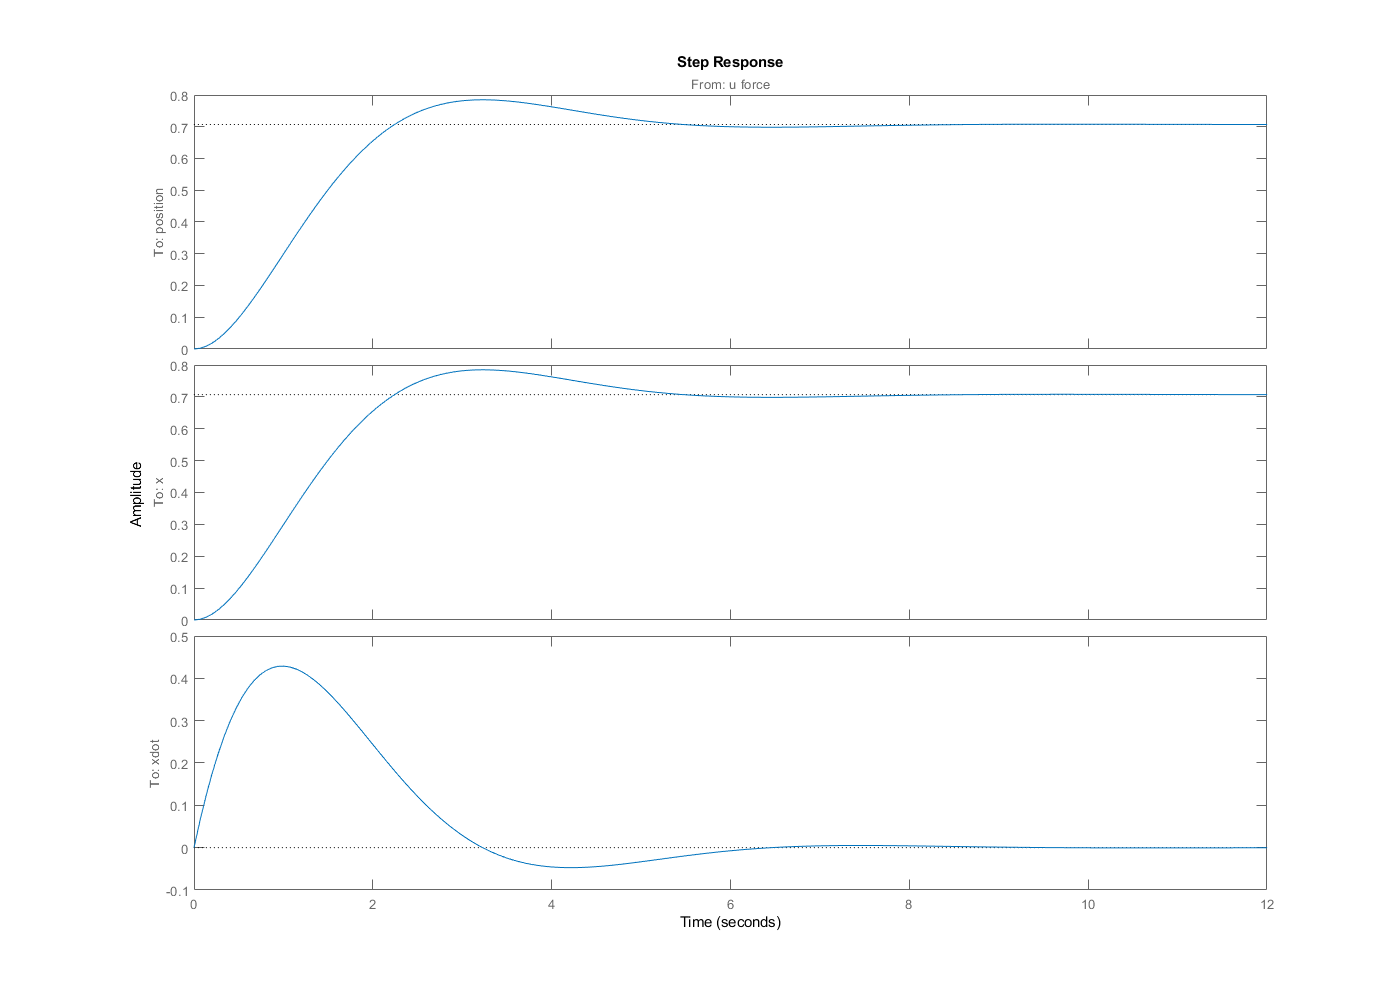

step(LQR_plant)

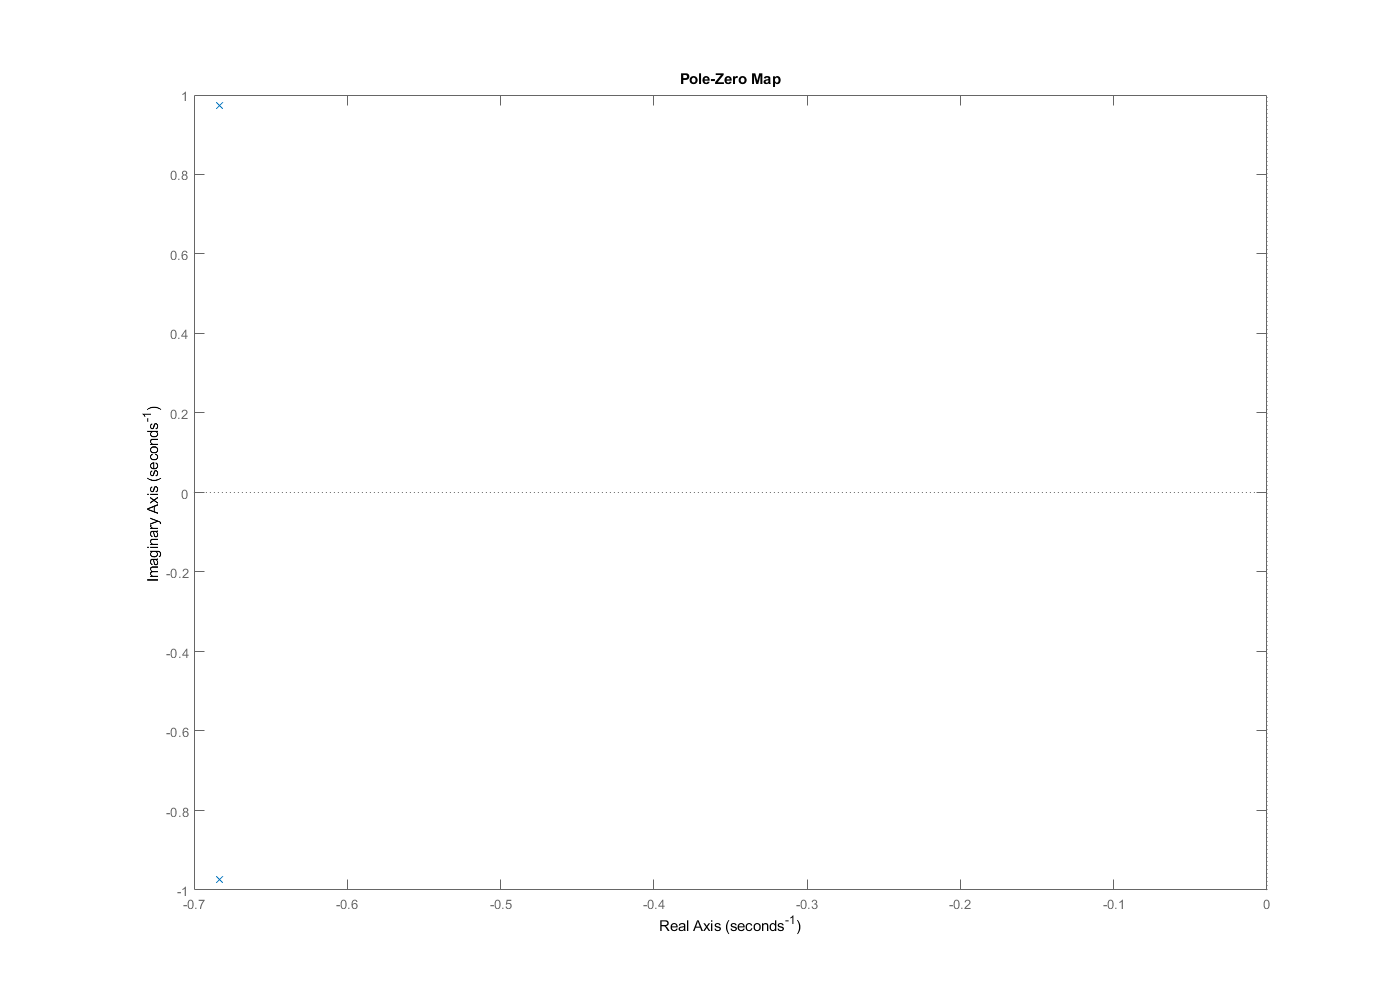

pzplot(LQR_plant)

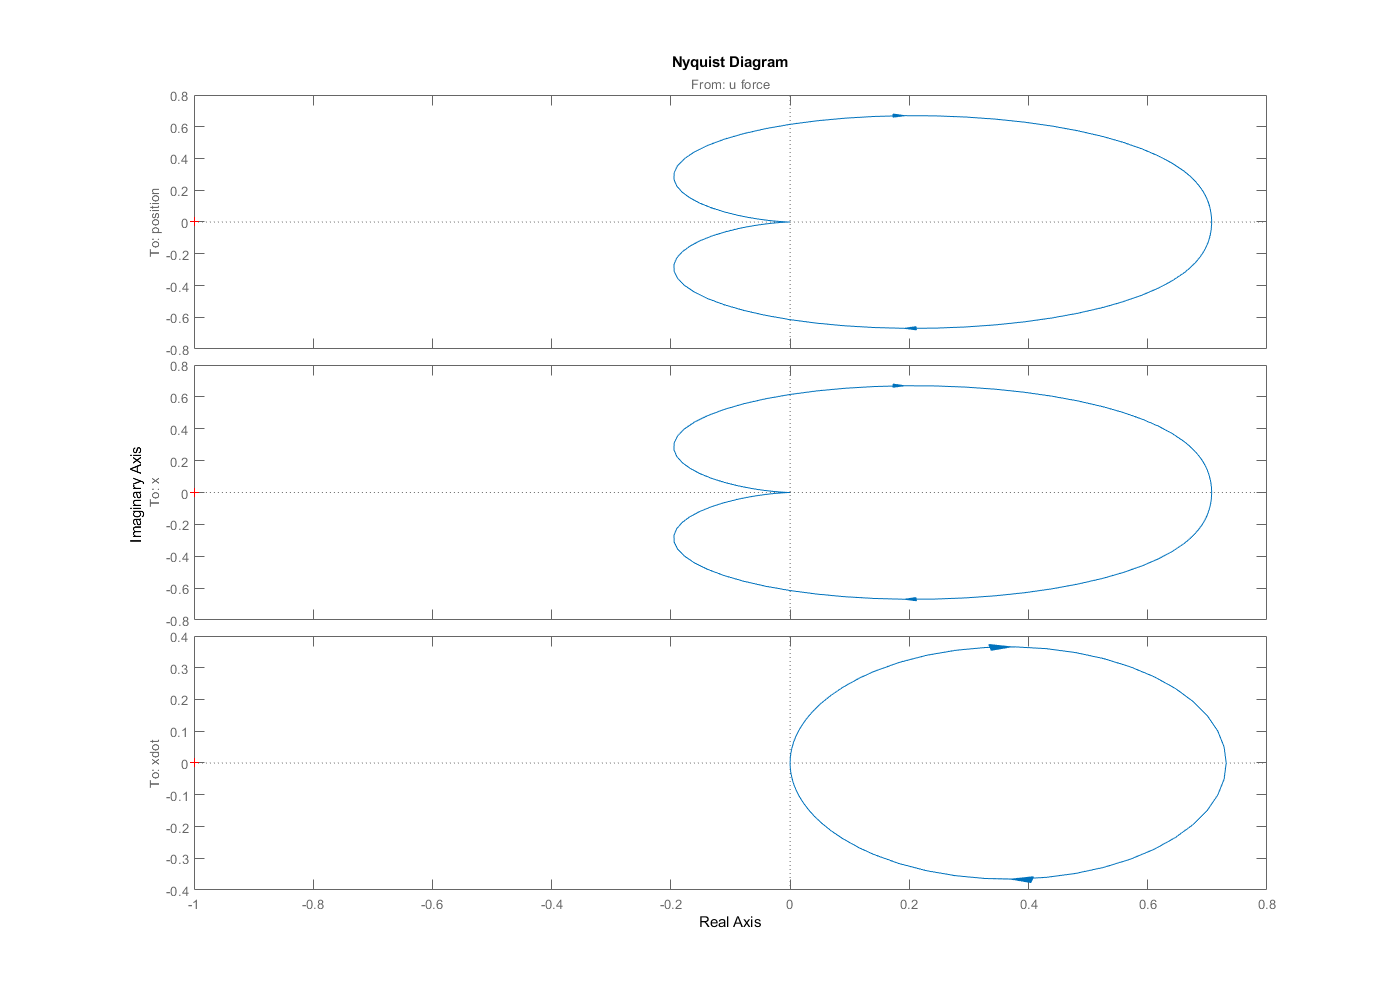

nyquist(LQR_plant)

### Hinf

#### Parameters (gains)

cutoff_hz = 120

cutoff_hz = 120

wc = 2*pi*cutoff_hz;
We = tf([0,wc],[1,wc]);

cutoff_hz = 610

cutoff_hz = 610

wc = 2*pi*cutoff_hz;
Wu = tf([0,1],[1,wc]);

Winput = tf([0,1],[0,1]);

Wsensor = tf([0,1],[0,1]);


#### Genarlized Plant

P = tf(plant)


P =
 
  From input "u force" to output "position":
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_INF,~,Gam,info_inf] = hinfsyn(G,1,1,[0,1.2],'DISPLAY','on');


  Test bounds:  0.968 <=  gamma  <=  1.2

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.20e+00     1.4e-08     0.0e+00     2.531e-02     p
  1.08e+00     1.4e-08     0.0e+00     5.065e-02     p
  1.02e+00     1.4e-08     0.0e+00     9.839e-02     p
  9.94e-01     1.4e-08     0.0e+00     2.029e-01     p
  9.81e-01     1.4e-08     0.0e+00     5.381e-01     p
  9.74e-01    -1.8e+02 #  -1.6e-15     5.908e-06     f
  Limiting gains...
  9.84e-01     1.4e-07     0.0e+00     3.768e-01     p
  9.84e-01     1.4e-06     0.0e+00     3.770e-01     p
  9.84e-01     1.1e-05     0.0e+00     3.802e-01     p
  9.84e-01     2.9e-05     0.0e+00     5.868e-01     p
  9.84e-01    -9.0e+00 #  -3.9e-16     2.987e-05     f

  Best performance (actual): 0.984



controller = ss(K_INF);
controller.InputName = {'position'};
controller.OutputName={'u force'};
Hinf_plant = feedback(plant_aug,controller,'name',+1);

### Responce

report.hinf = test_plant(Hinf_plant)

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
    cascade: [1×1 struct]
         h2: [1×1 struct]


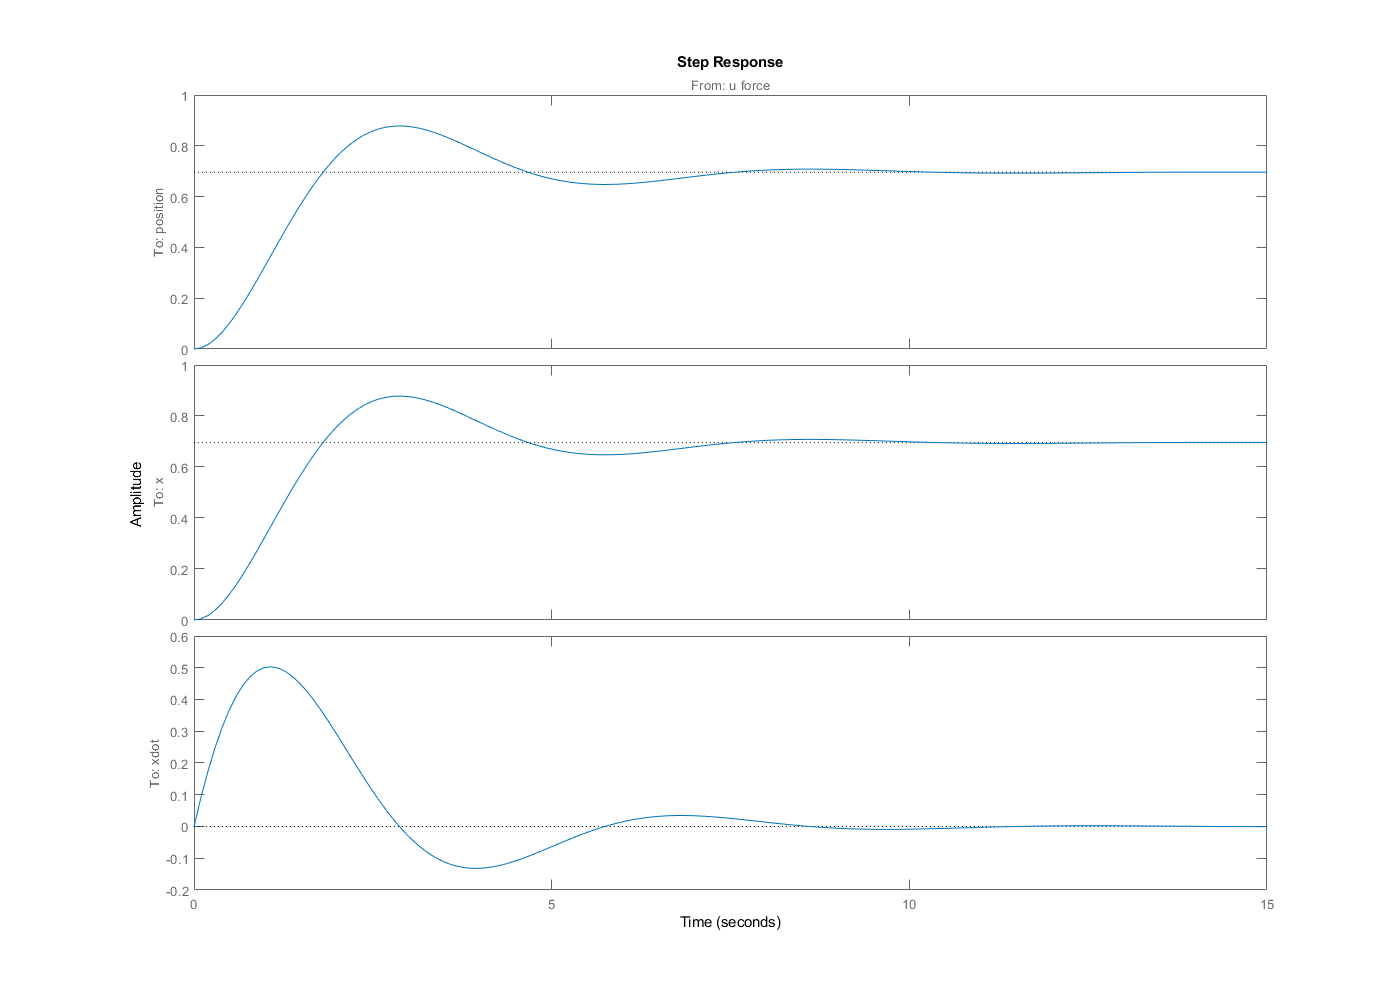

step(Hinf_plant)

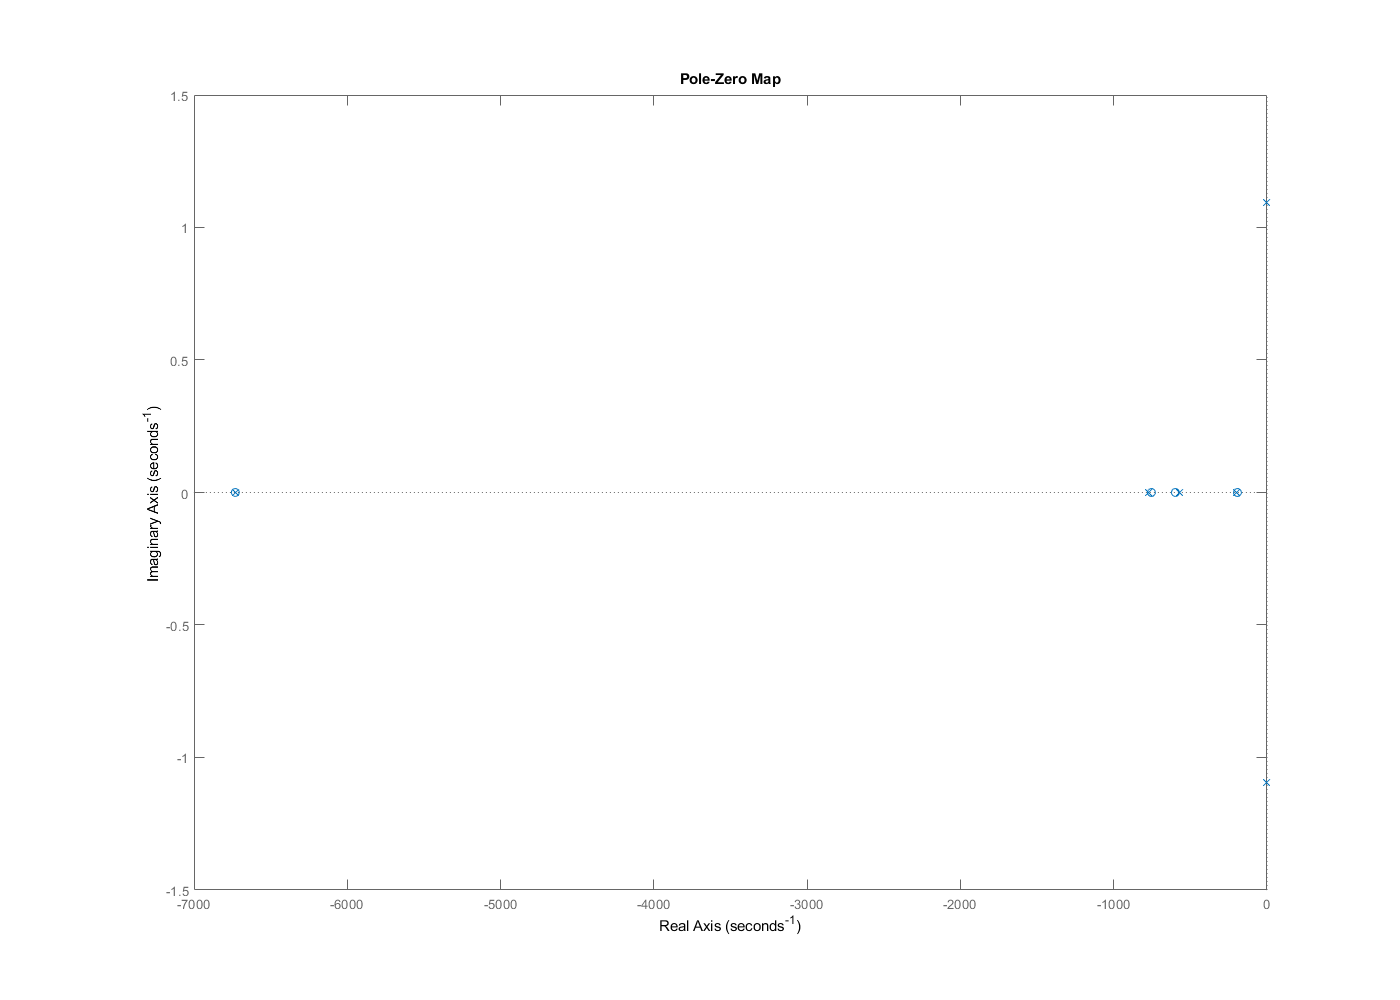

pzplot(Hinf_plant)

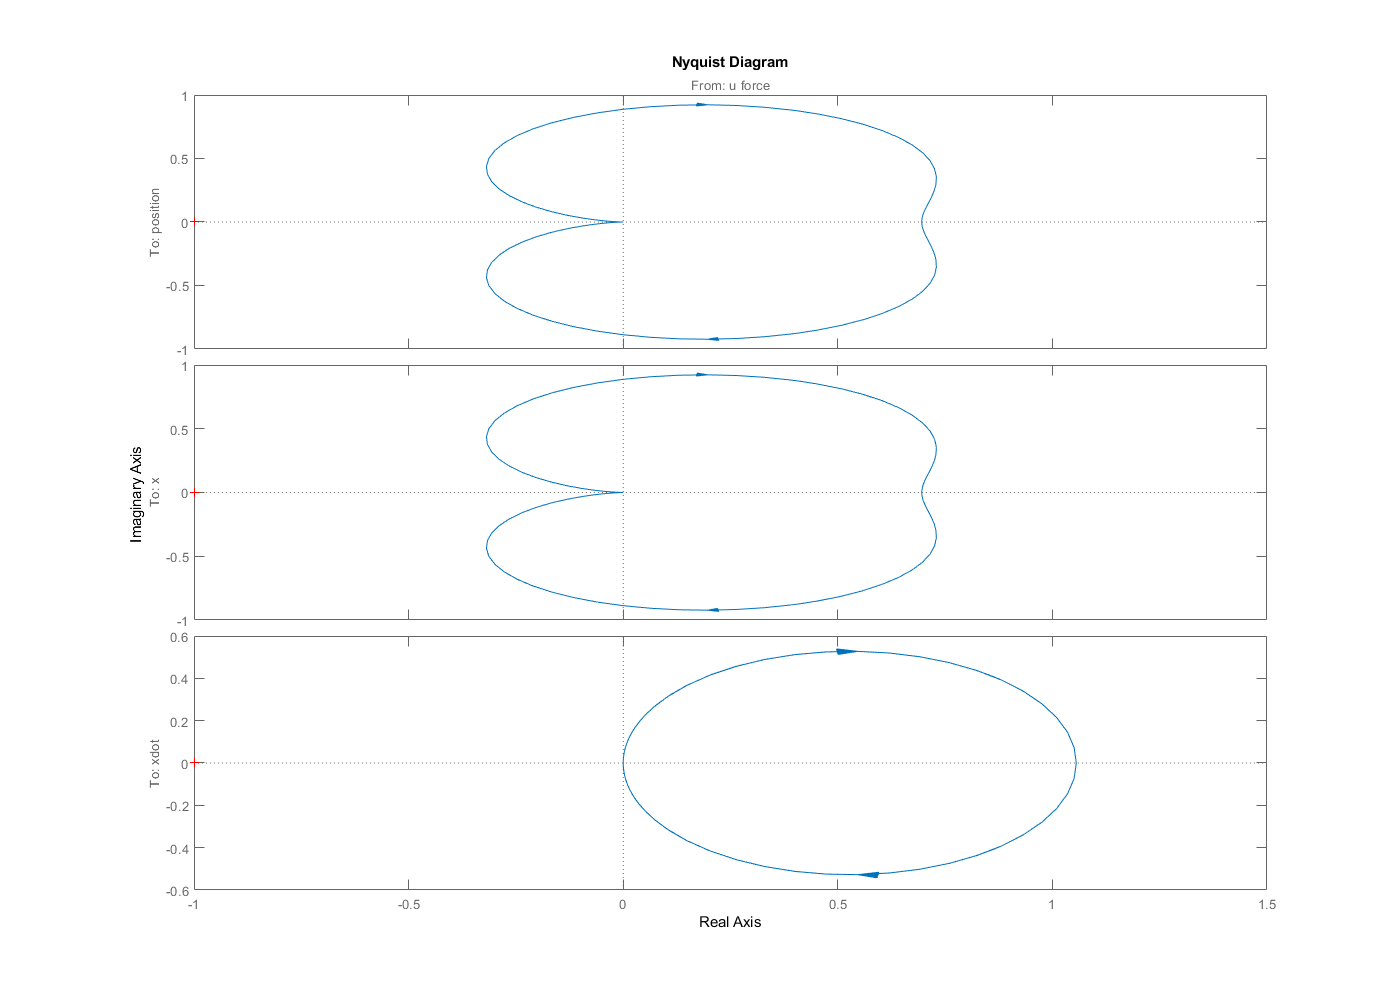

nyquist(Hinf_plant)

### H2

#### Parameters (gains)

cutoff_hz = 120

cutoff_hz = 120

wc = 2*pi*cutoff_hz;
We = tf([0,wc],[1,wc]);

cutoff_hz = 610

cutoff_hz = 610

wc = 2*pi*cutoff_hz;
Wu = tf([0,1],[1,wc]);

Winput = tf([0,1],[0,1]);

Wsensor = tf([0,1],[0,1]);


#### Genarlized Plant

P = tf(plant)


P =
 
  From input "u force" to output "position":
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_2,~,Gam,info_2] = h2syn(G,1,1);

controller = ss(K_2);
controller.InputName = {'position'};
controller.OutputName={'u force'};
H2_plant = feedback(plant_aug,controller,'name',+1);

### Responce

report.h2 = test_plant(H2_plant)

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
    cascade: [1×1 struct]
         h2: [1×1 struct]


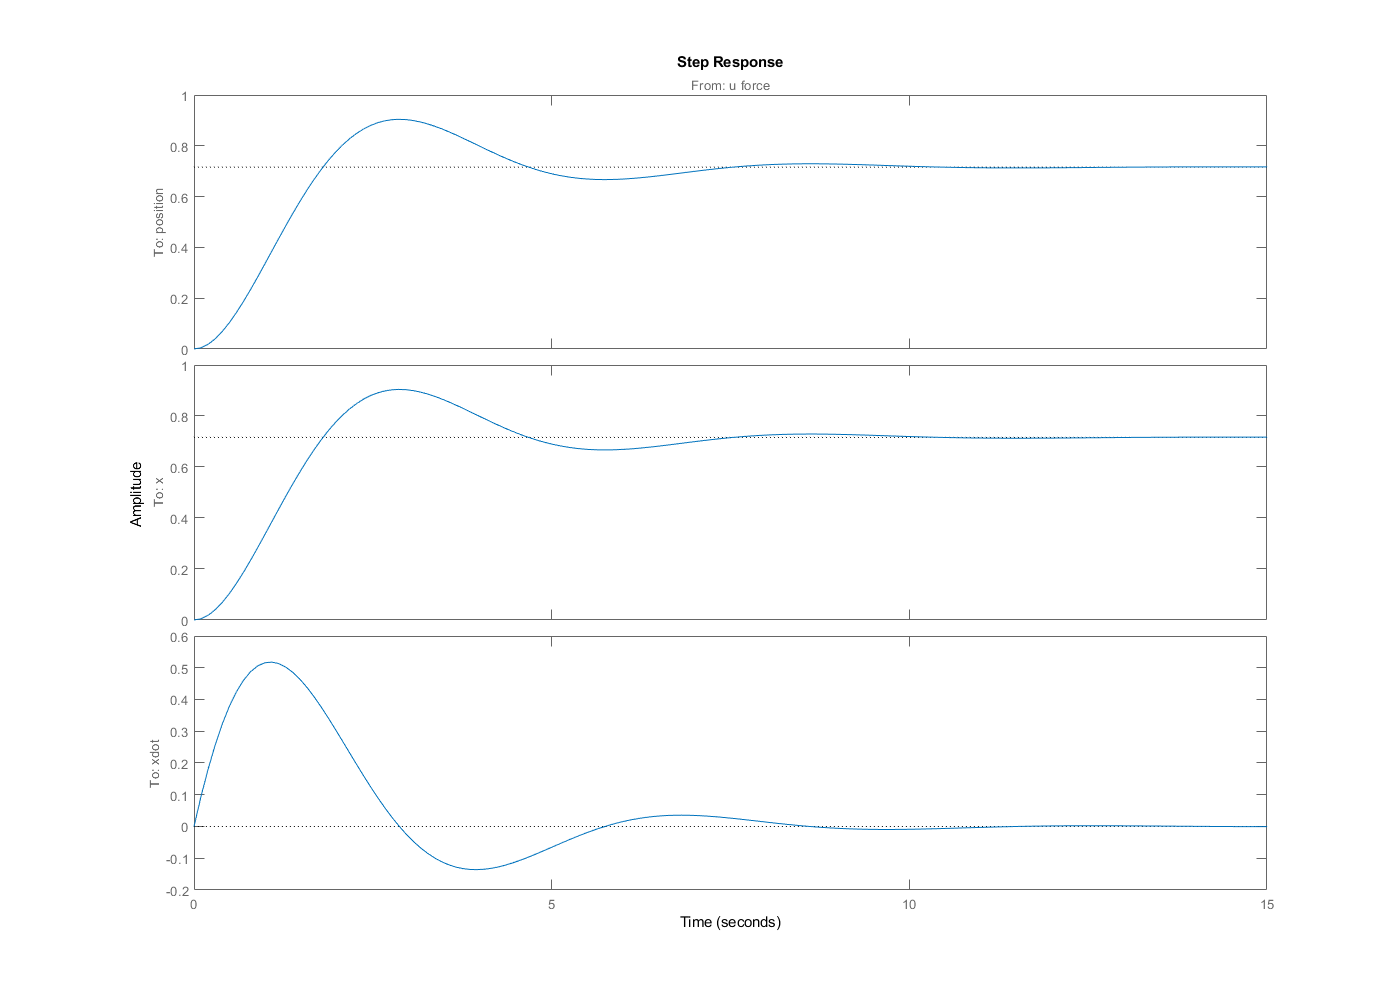

step(H2_plant)

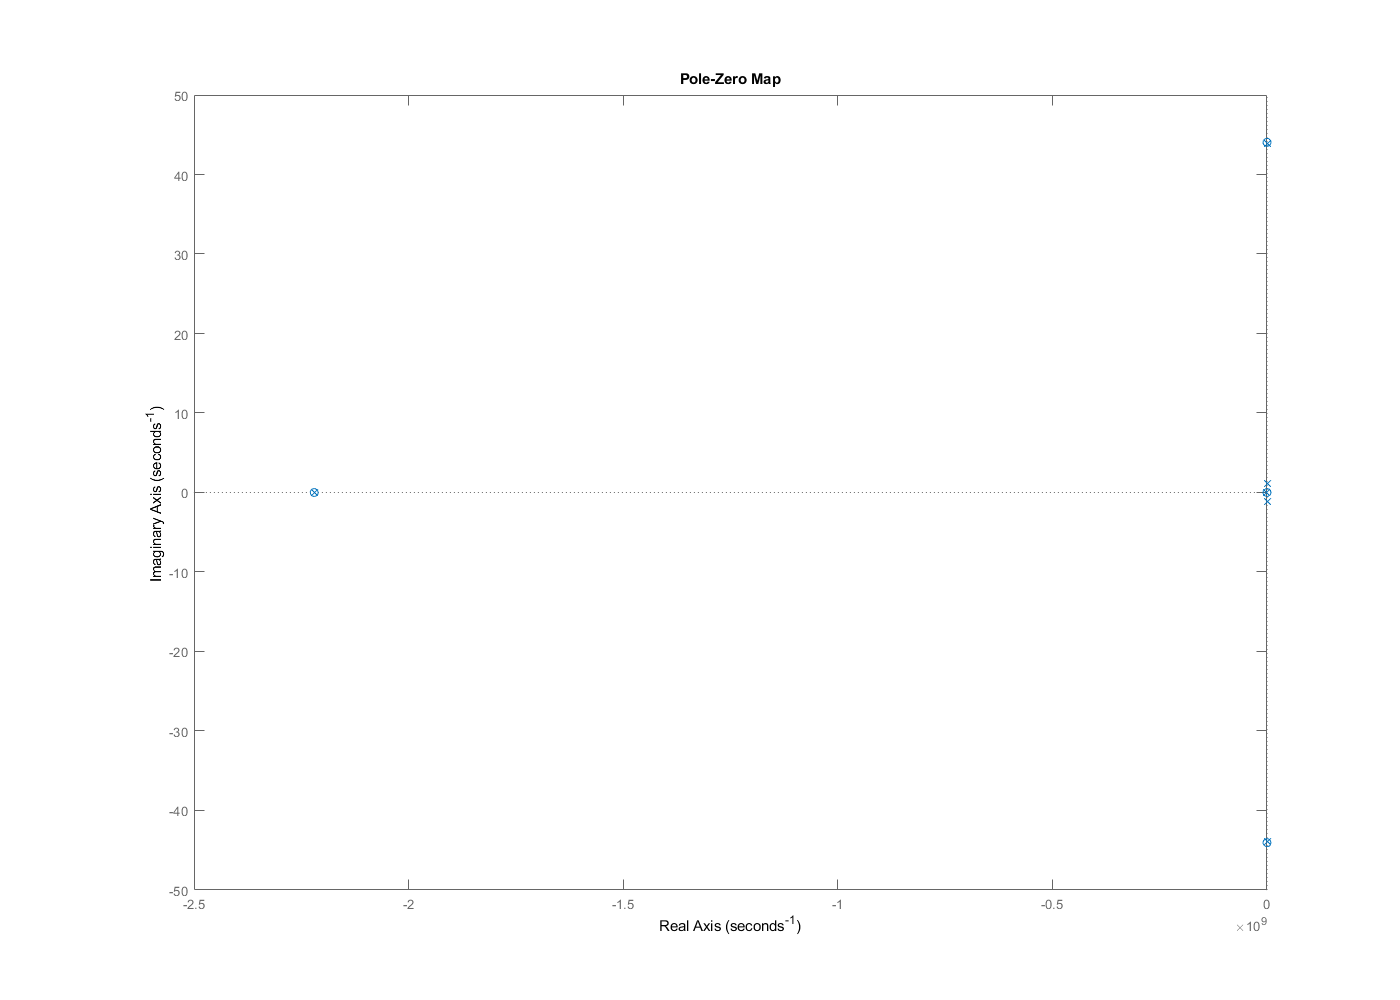

pzplot(H2_plant)

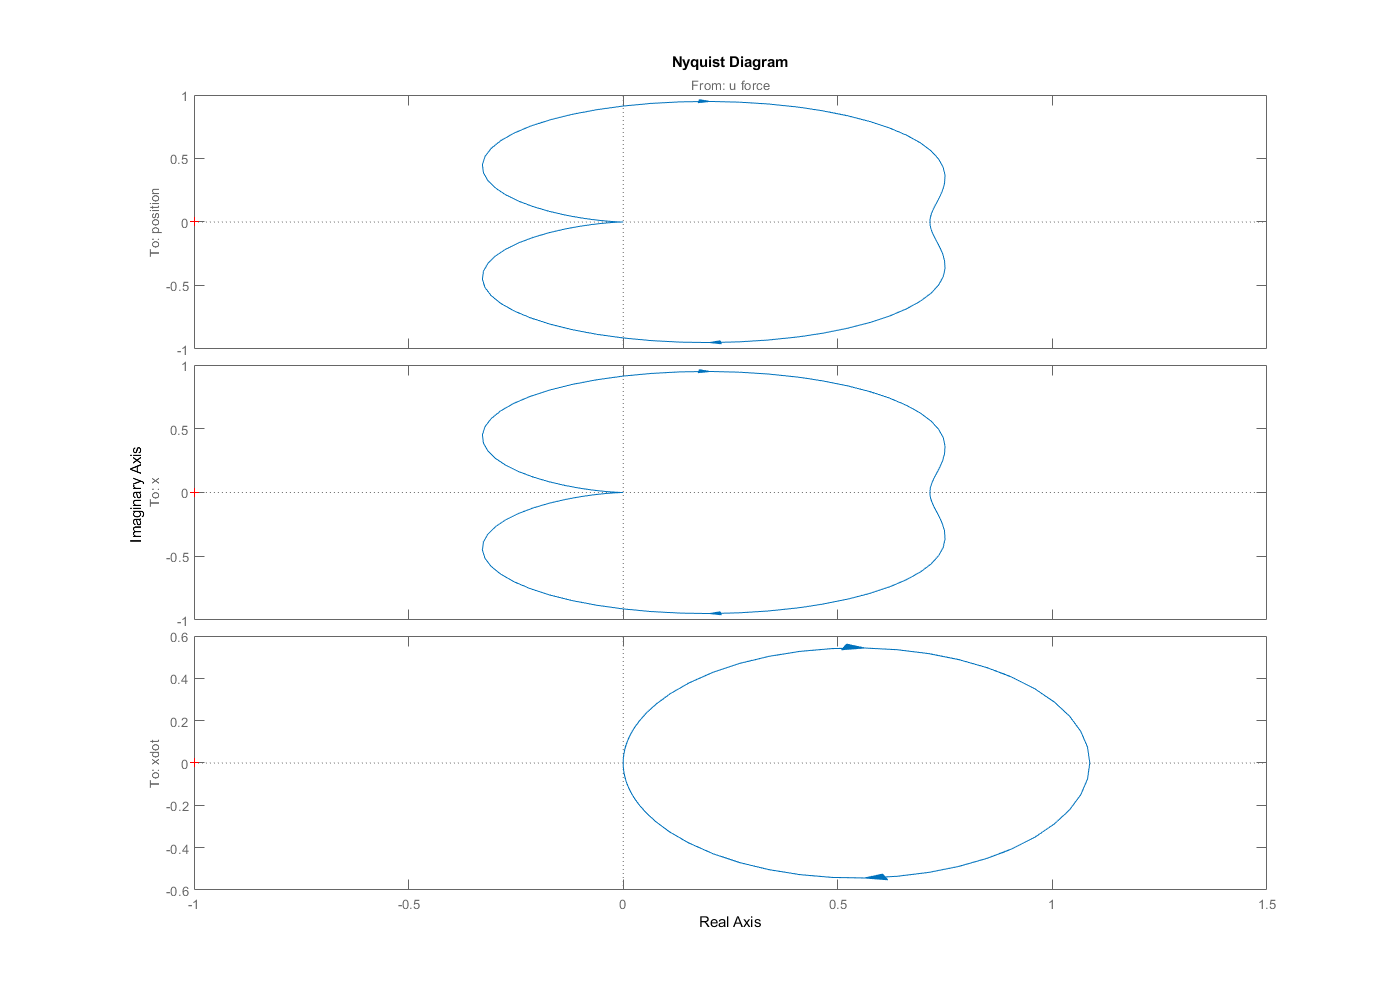

nyquist(H2_plant)

### Cascade Control

#### LQR Closed Loop Plant

plant_CL = ss(LQR_plant.A,LQR_plant.B,LQR_plant.C(1,:),LQR_plant.D(1));
plant_CL.InputName = {'u force'};
plant_CL.StateName={'x','xdot'};
plant_CL.OutputName={'position'};

#### Parameters (gains) calcualted above in the Hinf section

% cutoff_hz = 120
% wc = 2*pi*cutoff_hz;
% We = tf([0,wc],[1,wc]);
% 
% cutoff_hz = 610
% wc = 2*pi*cutoff_hz;
% Wu = tf([0,1],[1,wc]);
% 
% Winput = tf([0,1],[0,1]);
% 
% Wsensor = tf([0,1],[0,1]);

#### Controler

P = tf(plant_CL)


P =
 
  From input "u force" to output "position":
            1
  ---------------------
  s^2 + 1.367 s + 1.414
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_INF,~,Gam,info_inf] = hinfsyn(G,1,1,[0,1.2],'DISPLAY','on');


  Test bounds:  0.968 <=  gamma  <=  1.2

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.20e+00     1.2e-08     0.0e+00     7.420e-03     p
  1.08e+00     1.2e-08     0.0e+00     1.485e-02     p
  1.02e+00     1.2e-08     0.0e+00     2.887e-02     p
  9.94e-01     1.2e-08     0.0e+00     5.956e-02     p
  9.81e-01     1.2e-08     0.0e+00     1.580e-01     p
  9.74e-01    -1.2e+02 #  -3.6e-15     2.246e-06     f
  Limiting gains...
  9.84e-01     1.2e-07     0.0e+00     1.106e-01     p
  9.84e-01     1.2e-06     0.0e+00     1.107e-01     p
  9.84e-01     1.0e-05     0.0e+00     1.114e-01     p
  9.84e-01     2.7e-05     0.0e+00     1.558e-01     p
  9.84e-01    -6.4e+00 #  -2.9e-16     1.083e-05     f

  Best performance (actual): 0.983



controller = ss(K_INF);
controller.InputName = {'position'};
controller.OutputName={'u force'};
cascade_plant = feedback(plant_CL,controller,'name',+1);

### Responce

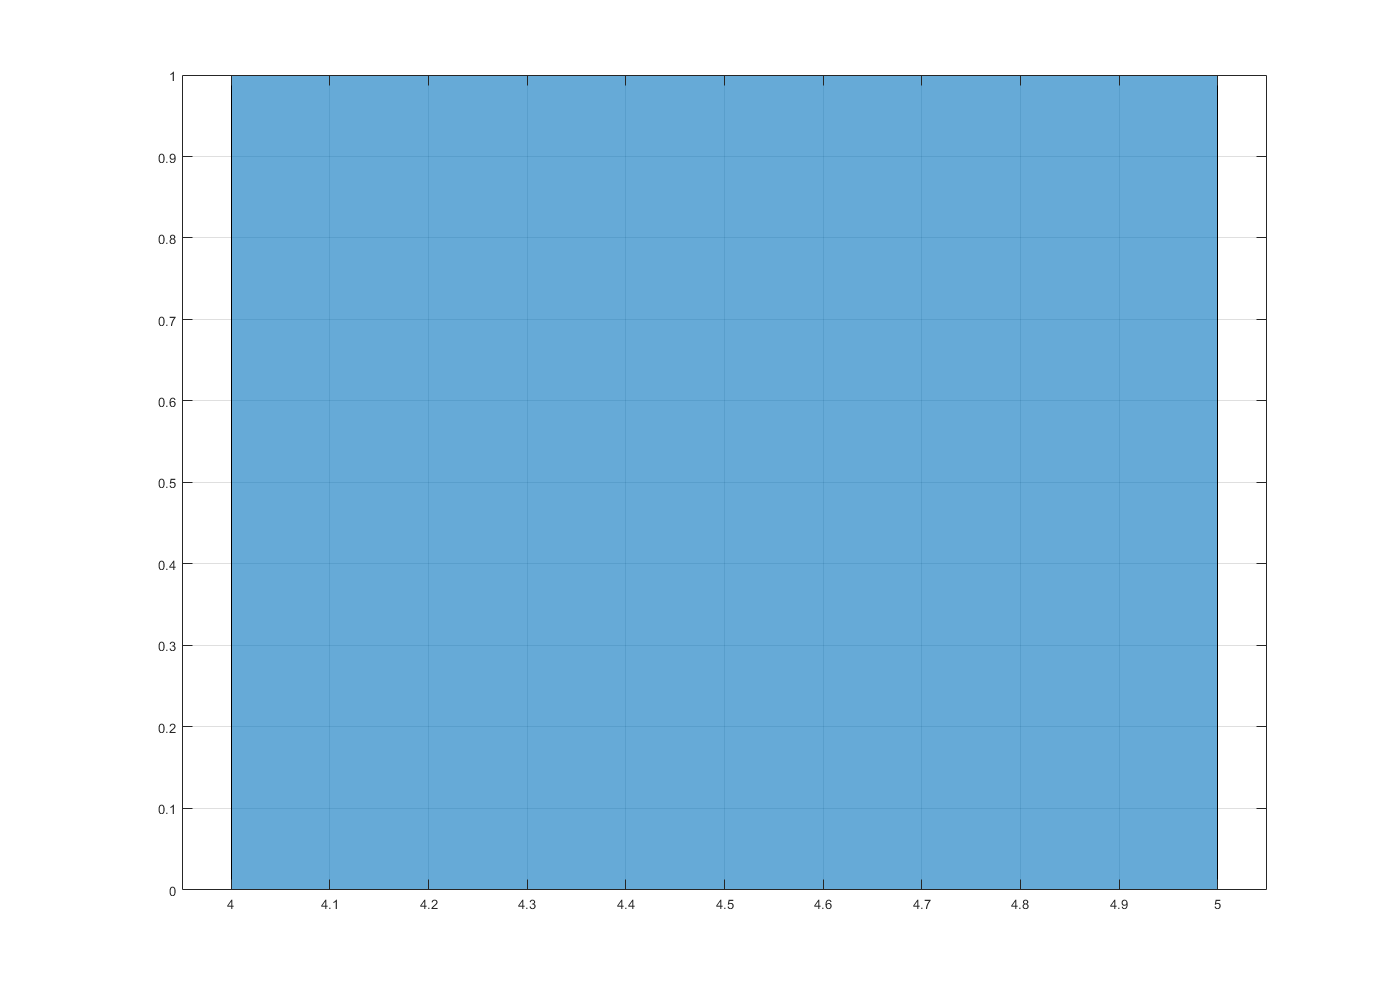

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
    cascade: [1×1 struct]
         h2: [1×1 struct]


report.cascade = test_plant(cascade_plant)

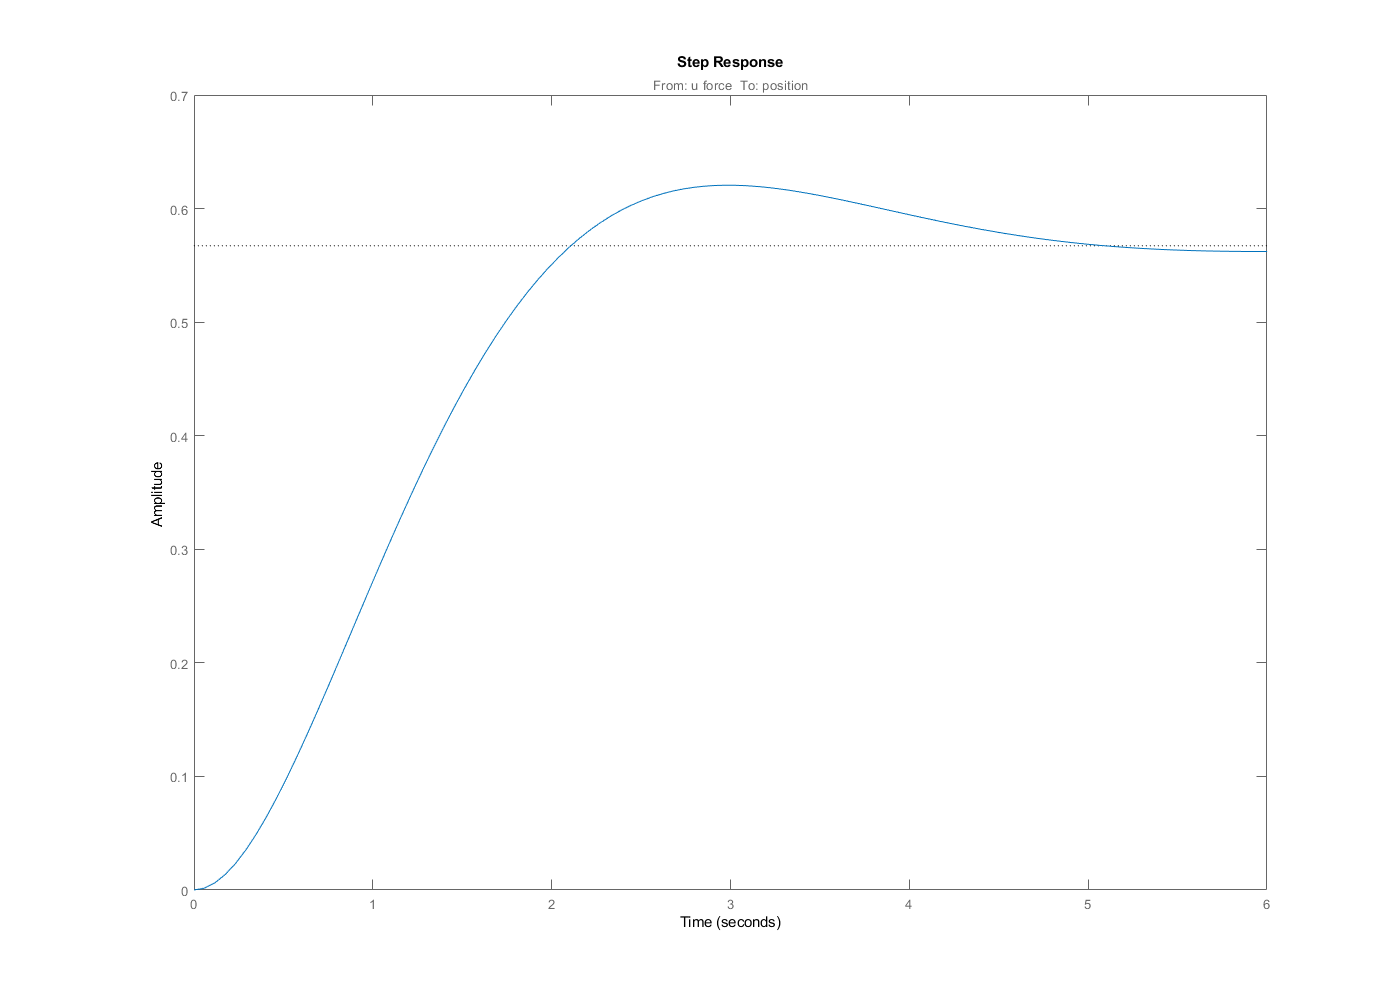

step(cascade_plant)

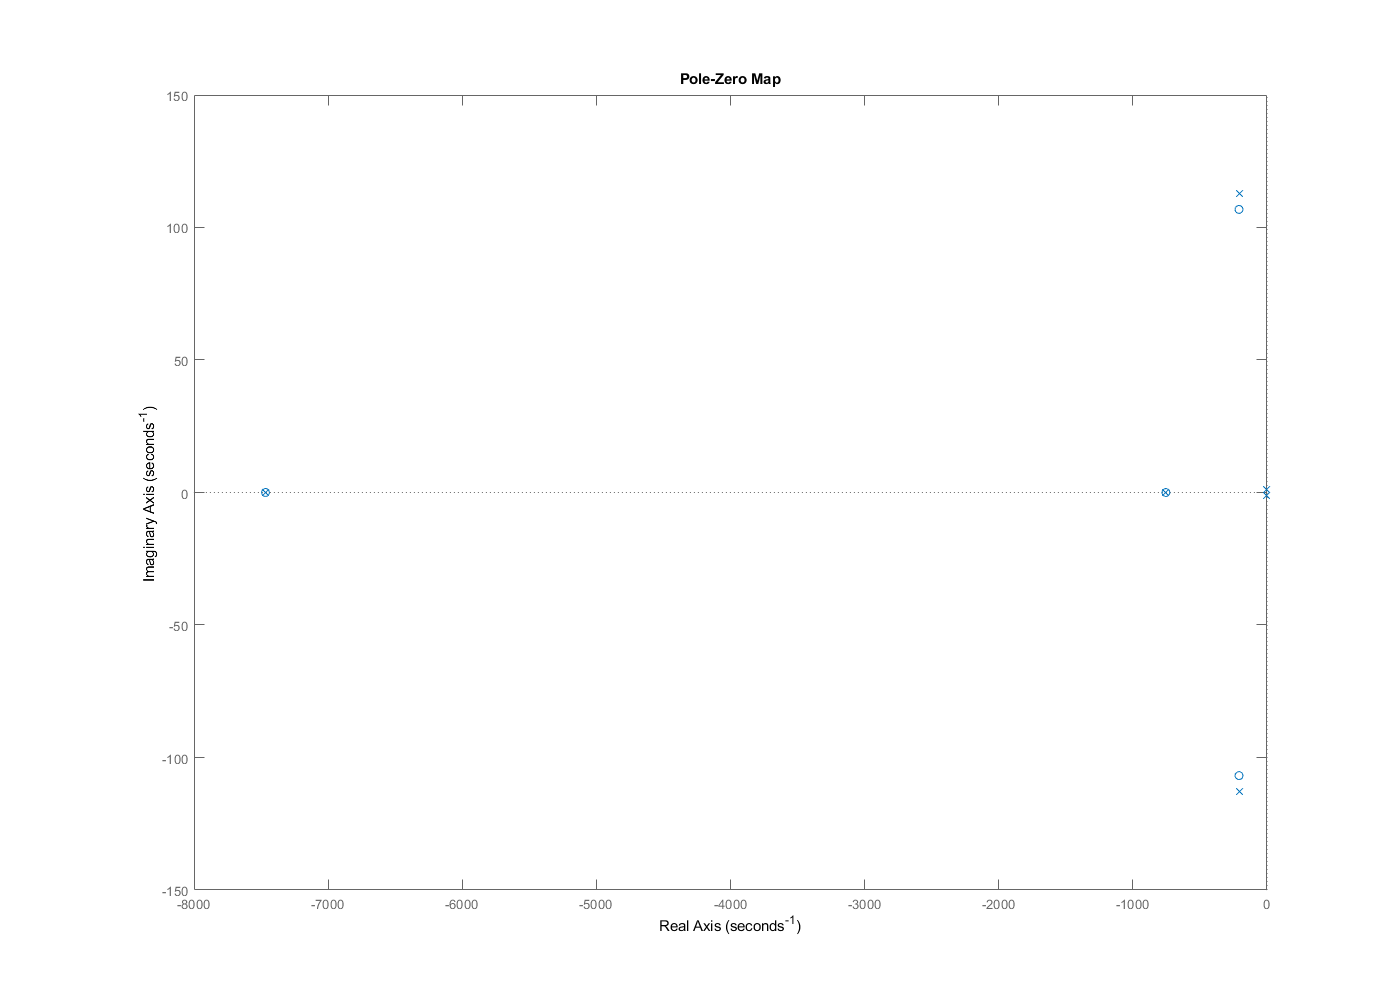

pzplot(cascade_plant)

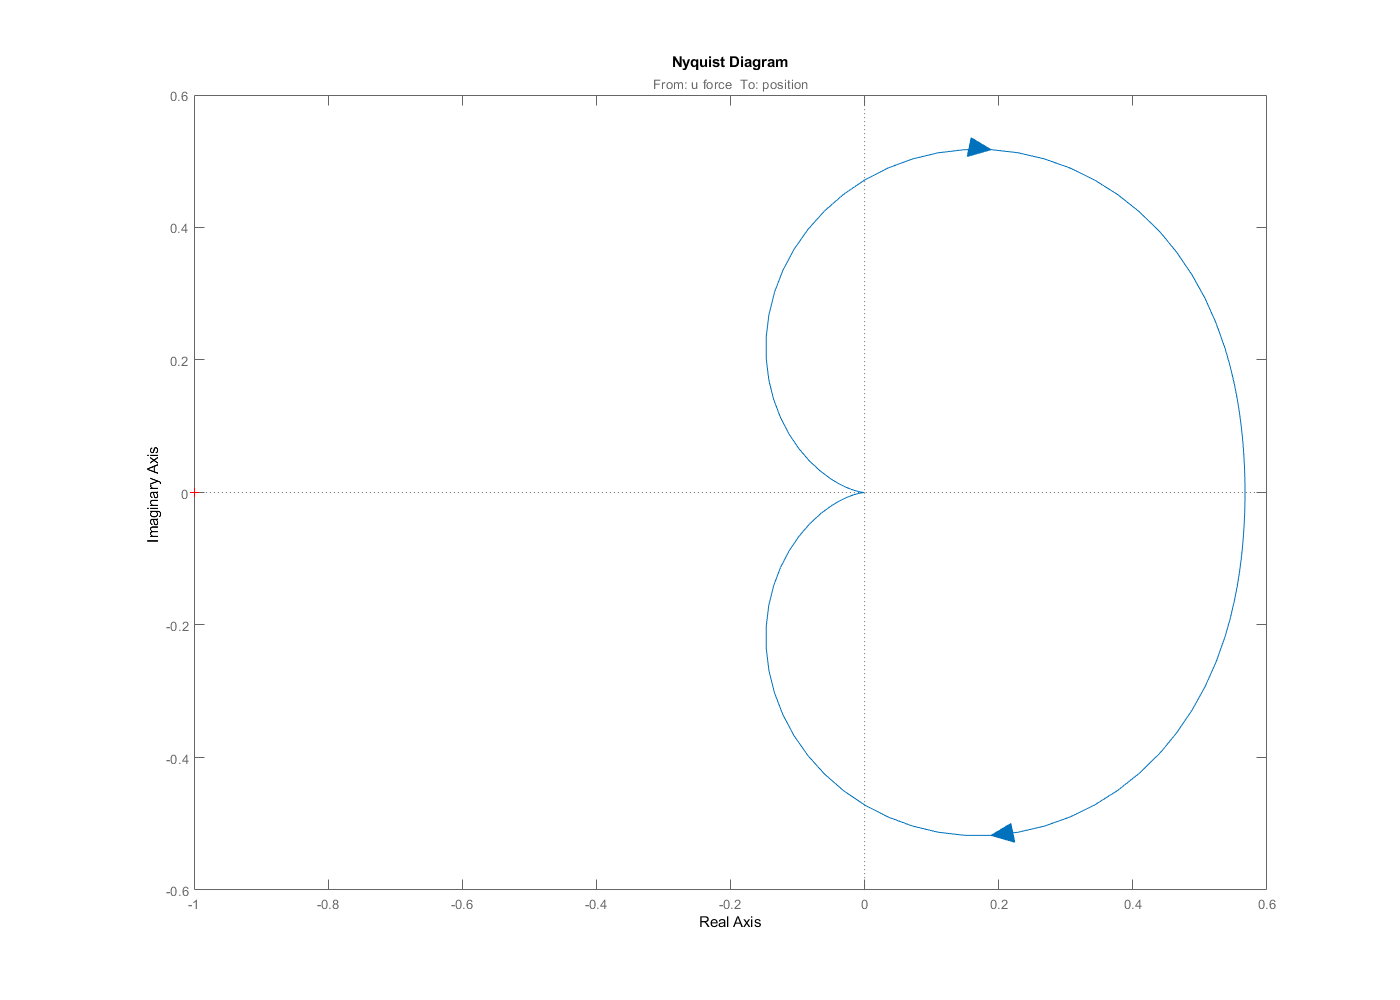

nyquist(cascade_plant)